%% Seven-DoF Robot Damping Comparison
% File: seven_dof_robot_damping_comparison.m

clear all;
close all;

%% Initialize DQ Robotics
include_namespace_dq;

%% Define Robot
DH_matrix = [zeros(1,7);   % theta
             zeros(1,7);   % d
             ones(1,7);    % a = 1
             zeros(1,7);   % alpha
             zeros(1,7)];  % rotational joints

robot = DQ_SerialManipulatorDH(DH_matrix, 'standard');
robot.name = '7-DoF Planar Robot';

fprintf('7-DoF Robot Damping Comparison\n\n');

7-DoF Robot Damping Comparison




%% Simulation Parameters
dt = 0.001;
t_total = 10;
iterations = round(t_total/dt);
gain = 10;

%% Damping Values
damping_values = [0.001, 0.01, 0.1, 0.2, 0.3, 0.4, 0.5, 1];

%% Condition 1: Singular Configuration
fprintf('=== Condition 1: Singular Configuration ===\n');

=== Condition 1: Singular Configuration ===


q_init_1 = zeros(7, 1);
t_d = 7;
eta = 10;
epsilon = 0.01;

xd_1 = t_d + DQ.i * eta;

% Run controllers for Condition 1
num_ctrl = 9;
error_1 = zeros(num_ctrl, iterations);
control_1 = zeros(num_ctrl, iterations);
names = cell(num_ctrl, 1);

names{1} = 'SVD';
for i = 1:8
    names{i+1} = sprintf('λ=%.3f', damping_values(i));
end

for ctrl = 1:num_ctrl
    q = q_init_1;
    
    for k = 1:iterations
        x = robot.fkm(q);
        x_trans = vec3(translation(x));
        xd_trans = vec3(xd_1);
        error = xd_trans - x_trans;
        
        error_1(ctrl, k) = norm(error);
        
        J = robot.pose_jacobian(q);
        Jt = [J(2,:); J(4,:); J(6,:)];
        
        if ctrl == 1
            u = gain * pinv(Jt) * error;
        else
            lambda = damping_values(ctrl - 1);
            u = gain * Jt' * inv(Jt * Jt' + lambda^2 * eye(3)) * error;
        end
        
        control_1(ctrl, k) = norm(u);
        q = q + u * dt;
    end
end

fprintf('Condition 1 complete\n\n');

Condition 1 complete




%% Condition 2: Normal Configuration
fprintf('=== Condition 2: Normal Configuration ===\n');

=== Condition 2: Normal Configuration ===


q_init_2 = (pi/12) * ones(7, 1);
xd_2 = 7 + DQ.i * 10;

error_2 = zeros(num_ctrl, iterations);
control_2 = zeros(num_ctrl, iterations);

for ctrl = 1:num_ctrl
    q = q_init_2;
    
    for k = 1:iterations
        x = robot.fkm(q);
        x_trans = vec3(translation(x));
        xd_trans = vec3(xd_2);
        error = xd_trans - x_trans;
        
        error_2(ctrl, k) = norm(error);
        
        J = robot.pose_jacobian(q);
        Jt = [J(2,:); J(4,:); J(6,:)];
        
        if ctrl == 1
            u = gain * pinv(Jt) * error;
        else
            lambda = damping_values(ctrl - 1);
            u = gain * Jt' * inv(Jt * Jt' + lambda^2 * eye(3)) * error;
        end
        
        control_2(ctrl, k) = norm(u);
        q = q + u * dt;
    end
end

fprintf('Condition 2 complete\n\n');

Condition 2 complete



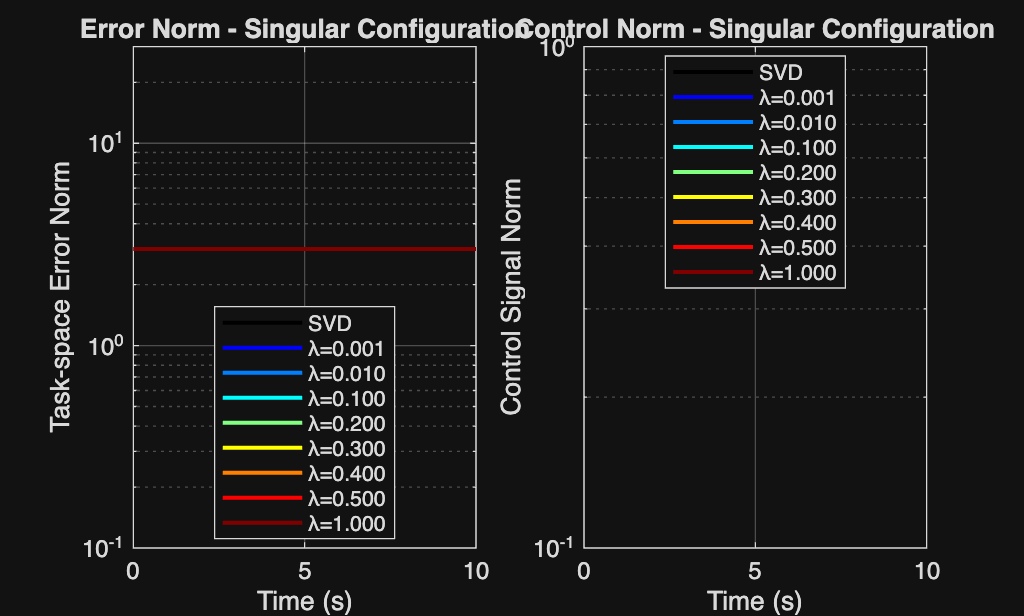


%% Plot Results
time = (0:iterations-1) * dt;

% Condition 1 Plots
figure('Name', 'Condition 1: Singular Configuration');

subplot(1, 2, 1);
colors = [0 0 0; jet(8)];
for ctrl = 1:num_ctrl
    semilogy(time, error_1(ctrl,:), 'LineWidth', 1.5, 'Color', colors(ctrl,:), ...
             'DisplayName', names{ctrl});
    hold on;
end
grid on;
xlabel('Time (s)');
ylabel('Task-space Error Norm');
title('Error Norm - Singular Configuration');
legend('Location', 'best', 'FontSize', 8);
hold off;

subplot(1, 2, 2);
for ctrl = 1:num_ctrl
    semilogy(time, control_1(ctrl,:), 'LineWidth', 1.5, 'Color', colors(ctrl,:), ...
             'DisplayName', names{ctrl});
    hold on;
end
grid on;
xlabel('Time (s)');
ylabel('Control Signal Norm');
title('Control Norm - Singular Configuration');
legend('Location', 'best', 'FontSize', 8);
hold off;

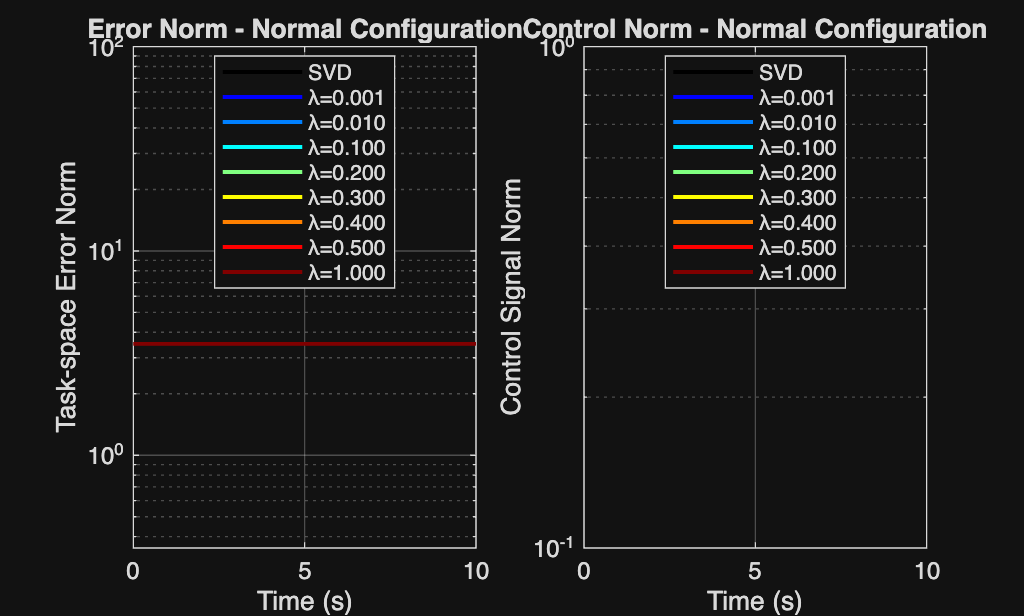


% Condition 2 Plots
figure('Name', 'Condition 2: Normal Configuration');

subplot(1, 2, 1);
for ctrl = 1:num_ctrl
    semilogy(time, error_2(ctrl,:), 'LineWidth', 1.5, 'Color', colors(ctrl,:), ...
             'DisplayName', names{ctrl});
    hold on;
end
grid on;
xlabel('Time (s)');
ylabel('Task-space Error Norm');
title('Error Norm - Normal Configuration');
legend('Location', 'best', 'FontSize', 8);
hold off;

subplot(1, 2, 2);
for ctrl = 1:num_ctrl
    semilogy(time, control_2(ctrl,:), 'LineWidth', 1.5, 'Color', colors(ctrl,:), ...
             'DisplayName', names{ctrl});
    hold on;
end
grid on;
xlabel('Time (s)');
ylabel('Control Signal Norm');
title('Control Norm - Normal Configuration');
legend('Location', 'best', 'FontSize', 8);
hold off;


%% Final Statistics
fprintf('=== Final Statistics ===\n\n');

=== Final Statistics ===




fprintf('Condition 1 (Singular):\n');

Condition 1 (Singular):


for ctrl = 1:num_ctrl
    fprintf('%s:\n', names{ctrl});
    fprintf('  Final error: %.6e\n', error_1(ctrl, end));
    fprintf('  Max control: %.6e\n', max(control_1(ctrl,:)));
    fprintf('  Mean control: %.6e\n\n', mean(control_1(ctrl,:)));
end

SVD:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.001:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.010:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.100:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.200:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.300:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.400:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.500:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=1.000:


  Final error: 3.000000e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00




fprintf('Condition 2 (Normal):\n');

Condition 2 (Normal):


for ctrl = 1:num_ctrl
    fprintf('%s:\n', names{ctrl});
    fprintf('  Final error: %.6e\n', error_2(ctrl, end));
    fprintf('  Max control: %.6e\n', max(control_2(ctrl,:)));
    fprintf('  Mean control: %.6e\n\n', mean(control_2(ctrl,:)));
end

SVD:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.001:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.010:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.100:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.200:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.300:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.400:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=0.500:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00



λ=1.000:


  Final error: 3.515453e+00


  Max control: 0.000000e+00


  Mean control: 0.000000e+00




fprintf('Comparison complete\n');

Comparison complete
